clear;

運動方程式と回転行列、角速度ベクトルをロード

load("dX.mat", "fdX");
load("R_BtoI.mat", "fR_BtoI");
load("Omega.mat", "fOmega");
load("P_BtoI.mat", "fP_BtoI");

初期値を設定

X0 = [0; 0; 0];    % 位置
dX0 = [0; 0; 0];   % 速度
Pos0 = [X0; dX0];

eta0 = [0; 0; 0];   % 角度
deta0 = [0; 0; 0];   % 角速度
Att0 = [eta0; deta0];

Current0 = [Pos0; Att0];

tspan = 0:0.01:100;      % シミュレーション時間

定数に値を入れる 

J_xx = 0.01; J_yy = 0.02; J_zz = 0.03; 
m = 1.7; g = 9.81; mu_1 = 0.1; mu_2 = 0.01; 
const = [J_xx; J_yy; J_zz; m; g; mu_1; mu_2];

% 外力 (例: すべて0)
F_b = [0; 0; 0];
Tau_b = [0; 0; 0];
Q_b = [F_b; Tau_b];


ode45でシミュレーション

options = odeset('RelTol',1e-6,'AbsTol',1e-6);
[ta, Current] = ode45(@(t, Current) system_dynamics(t, Current, Q_b, const, fdX, fR_BtoI, fOmega, fP_BtoI), tspan, Current0,options);


シミュレーション結果の取り出し

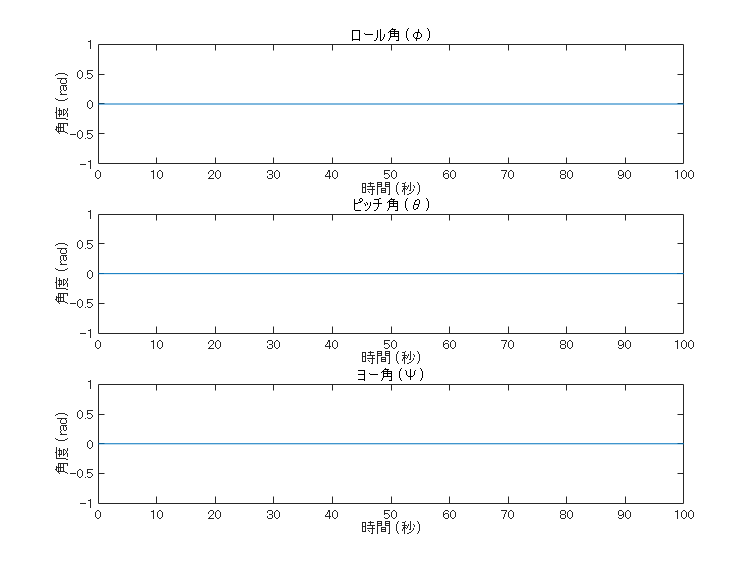

X_b_sim = Current(:, 1:3);
Eta_sim = Current(:, 4:6);
dX_b_sim = Current(:, 7:9);
dEta_sim = Current(:, 10:12);

figure(1); clf; hold on;
subplot(3,1,1);
plot(ta, Current(:,4));
title('ロール角 (φ)');
xlabel('時間 (秒)');
ylabel('角度 (rad)');
 
subplot(3,1,2);
plot(ta, Current(:,5));
title('ピッチ角 (θ)');
xlabel('時間 (秒)');
ylabel('角度 (rad)');
 
subplot(3,1,3);
plot(ta, Current(:,6));
title('ヨー角 (Ψ)');
xlabel('時間 (秒)');
ylabel('角度 (rad)');

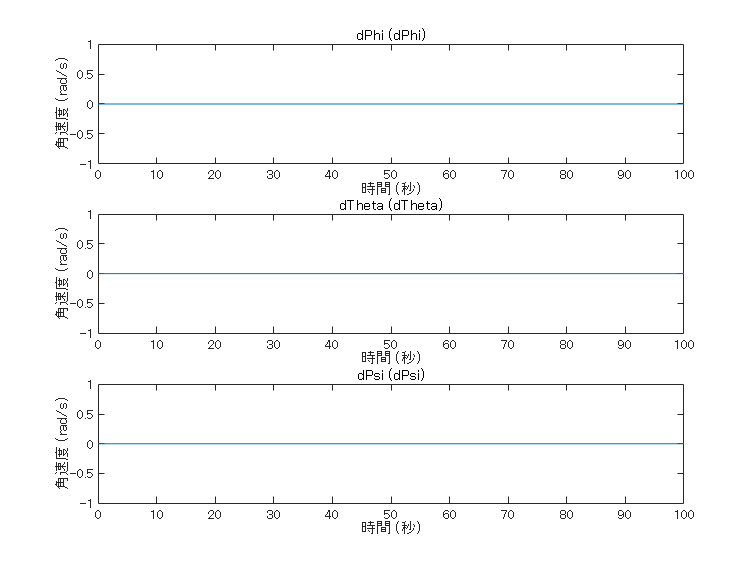


figure(2); clf; hold on;

subplot(3,1,1);
plot(ta, Current(:,10));
title('dPhi (dPhi)');
xlabel('時間 (秒)');
ylabel('角速度 (rad/s)');

subplot(3,1,2);
plot(ta, Current(:,11));
title('dTheta (dTheta)');
xlabel('時間 (秒)');
ylabel('角速度 (rad/s)');

subplot(3,1,3);
plot(ta, Current(:,12));
title('dPsi (dPsi)');
xlabel('時間 (秒)');
ylabel('角速度 (rad/s)');

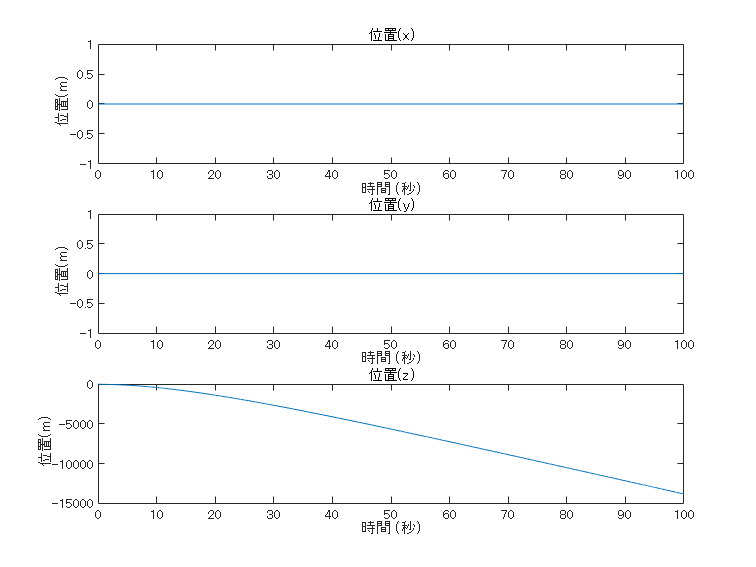


figure(3); clf; hold on;
subplot(3,1,1);
plot(ta, Current(:,1));
title('位置(x)');
xlabel('時間 (秒)');
ylabel(' 位置(m)');
 
subplot(3,1,2);
plot(ta, Current(:,2));
title('位置(y)');
xlabel('時間 (秒)');
ylabel(' 位置(m)');
 
subplot(3,1,3);
plot(ta, Current(:,3));
title('位置(z)');
xlabel('時間 (秒)');
ylabel(' 位置(m)');

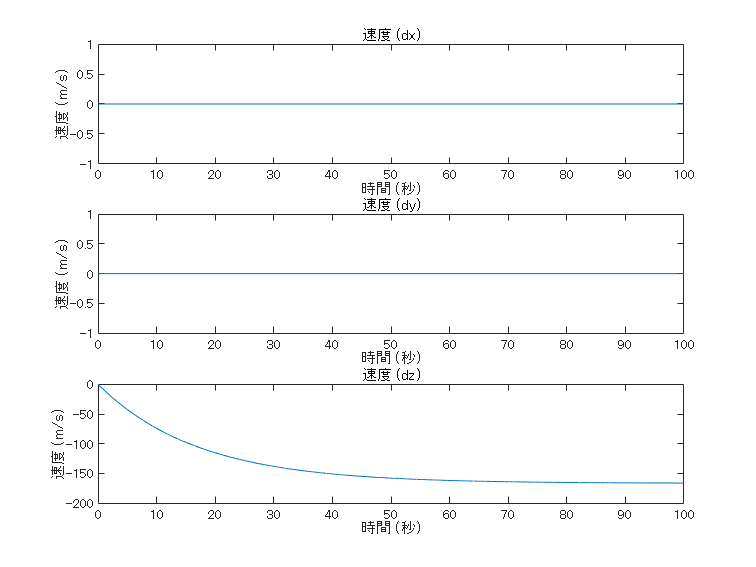


figure(4); clf; hold on;

subplot(3,1,1);
plot(ta, Current(:,7));
title('速度 (dx)');
xlabel('時間 (秒)');
ylabel('速度 (m/s)');

subplot(3,1,2);
plot(ta, Current(:,8));
title('速度 (dy)');
xlabel('時間 (秒)');
ylabel('速度 (m/s)');

subplot(3,1,3);
plot(ta, Current(:,9));
title('速度 (dz)');
xlabel('時間 (秒)');
ylabel('速度 (m/s)');


% system_dynamics
function dCurrent = system_dynamics(t, Current, Q_b, const, fdX, fR_BtoI, fOmega, fP_BtoI)
    % X_b = Current(1:3);
    Eta = Current(4:6);
    % dX_b = Current(7:9);
    dEta = Current(10:12);
    X = Current;
    F_b = Q_b(1:3);
    Tau_b = Q_b(4:6);

    R_BtoI = fR_BtoI(Eta);
    % Omega = fOmega([Eta; dEta]);
    P_BtoI = fP_BtoI(Eta);

    F_I = R_BtoI * F_b;
    Tau_I = P_BtoI * Tau_b;
    Q_I = [F_I; Tau_I];

    vars = {[X; Q_I; const]};
    fdx_val = fdX(vars{:});
    dCurrent = fdx_val;
end